clear all
clear

## Initial postion of guide and scout

mdl = "ConsolidatedModelV0";
open_system(mdl)


% create initial positon of guide, scout and  obstacles
L = 64;  % dimension of map
initPos =randi([1,L],3,2);
sGuide0 = [initPos(1,1) initPos(1,2)]; %  init guide location from random distribution
sScout0 =[initPos(2,1) initPos(2,2)];%  init scout location from random distribution
obstacleLoca = [ num2str(initPos(3,1))  num2str(initPos(3,2)) ]

obstacleLoca = '97'

s0 = [sGuide0;sScout0];
% create Map
gridMap = createGridWorld(L,L,'Kings') 

gridMap =   GridWorld with properties:

          GridSize: [64 64]
      CurrentState: "[1,1]"
            States: [4096×1 string]
           Actions: [8×1 string]
                 T: [4096×4096×8 double]
                 R: [4096×4096×8 double]
    ObstacleStates: [0×1 string]
    TerminalStates: [0×1 string]


gridMap.TerminalStates = ['[' num2str(sGuide0(1,1)) ',' num2str(sGuide0(1,2)) ']' ]

gridMap =   GridWorld with properties:

          GridSize: [64 64]
      CurrentState: "[1,1]"
            States: [4096×1 string]
           Actions: [8×1 string]
                 T: [4096×4096×8 double]
                 R: [4096×4096×8 double]
    ObstacleStates: [0×1 string]
    TerminalStates: "[53,59]"


gridMap.ObstacleStates = ['[' num2str(initPos(3,1)) ',' num2str(initPos(3,2)) ']' ]

gridMap =   GridWorld with properties:

          GridSize: [64 64]
      CurrentState: "[1,1]"
            States: [4096×1 string]
           Actions: [8×1 string]
                 T: [4096×4096×8 double]
                 R: [4096×4096×8 double]
    ObstacleStates: "[9,7]"
    TerminalStates: "[53,59]"


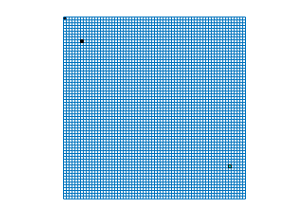

env = rlSimulinkEnv(mdl,{obs1Info,obs2Info},{act1Info,act2Info});
% Reset Function 
env.ResetFcn = @(in) resetFcn(in,obstacleLoca);
% Draw Map 
plot(env)

Hypeparameters

episode = 1; % initial training episodes
episodeMax = 5e5;% max training episodes


##  Max sample time and simulation time,Max Number of step s

Ts = 0.1;
Tf = 100;
maxsteps = ceil(Tf/Ts);

## Action space & Observation space

#### observation 1 and action 1 (Guide)

% obs info
obs1Size = [L L 4];
obs1Info = rlNumericSpec(obs1Size);
obs1Info.Name = "Observation";
obs1Info.Description = " observation for each agent is a 12x12x4 image";

% act info
act1Info = getActionInfo(env);


act1Info = 

  rlFiniteSetSpec with properties:

       Elements: [8×1 double]

           Name: "MDP Actions"

    Description: [0×0 string]

      Dimension: [1 1]

       DataType: "double"

#### reward  function

## Build Agent for Guide

% random number generator
rng(0)

Choose Type of RL Agents

RLAgentType = inputdlg("Guide/ Agent 1 Reinforcement Learning Type (PPO/DQN/DDPG/RL/ACAgent): ", "Choices",[1 50])

RLAgentType = 1×1 cell array
    {'PPO'}


RLAgentType = cell2mat(RLAgentType);
  switch RLAgentType

Create PPO Agent

      case "PPO"    
 actorNetWork1 = [
        imageInputLayer(obs1Size,'Normalization','none','Name','observations')
        convolution2dLayer(8,16,'Name','conv1','Stride',1,'Padding',1,'WeightsInitializer','he')
        reluLayer('Name','relu1')
        convolution2dLayer(4,8,'Name','conv2','Stride',1,'Padding','same','WeightsInitializer','he')
        reluLayer('Name','relu2')
        fullyConnectedLayer(64,'Name','fc1','WeightsInitializer','he')
        reluLayer('Name','relu3')
        fullyConnectedLayer(64,'Name','fc2','WeightsInitializer','he')
        reluLayer('Name','relu4')
        fullyConnectedLayer(64,'Name','fc3','WeightsInitializer','he')
        reluLayer('Name','relu5')
        fullyConnectedLayer(length(act1Info.Elements),'Name','output')
        softmaxLayer('Name','action')];
    actorNetWork1 = dlnetwork(actorNetWork1);
    
    % Create critic deep neural network.
  criticNetwork1 = [
        imageInputLayer(obs1Size,'Normalization','none','Name','observations')
        convolution2dLayer(8,16,'Name','conv1','Stride',1,'Padding',1,'WeightsInitializer','he')
        reluLayer('Name','relu1')
        convolution2dLayer(4,8,'Name','conv2','Stride',1,'Padding','same','WeightsInitializer','he')
        reluLayer('Name','relu2')
        fullyConnectedLayer(256,'Name','fc1','WeightsInitializer','he')
        reluLayer('Name','relu3')
        fullyConnectedLayer(128,'Name','fc2','WeightsInitializer','he')
        reluLayer('Name','relu4')
        fullyConnectedLayer(64,'Name','fc3','WeightsInitializer','he')
        reluLayer('Name','relu5')
        fullyConnectedLayer(1,'Name','output')];
    criticNetwork1 = dlnetwork(criticNetwork1); 

actor1 = rlDiscreteCategoricalActor(actorNetWork1,obs1Info,act1Info);  
    critic1 = rlValueFunction(criticNetwork1,obs1Info);

    actorOpts = rlOptimizerOptions('LearnRate',1e-4,'GradientThreshold',1,'Algorithm','adam');
    criticOpts = rlOptimizerOptions('LearnRate',1e-4,'GradientThreshold',1,'Algorithm','adam'); 

    opt = rlPPOAgentOptions(...
    'ActorOptimizerOptions',actorOpts,...
    'CriticOptimizerOptions',criticOpts,...
    'ExperienceHorizon',128,...
    'ClipFactor',0.2,...
    'EntropyLossWeight',0.01,...
    'MiniBatchSize',64,...
    'NumEpoch',3,...
    'AdvantageEstimateMethod','gae',...
    'GAEFactor',0.95,...
    'SampleTime',Ts,...                       %% Sample Time 
    'DiscountFactor',0.995);


    agent1 = rlPPOAgent(actor1,critic1,opt);

Create DQN Agent

case 'DQN'
    DQNInputSize = prod(obs1Size);
% create Depp Neural Network  &&& Define Paths
dnn = [imageInputLayer(obs1Size,'Normalization','none','Name','state')
    fullyConnectedLayer(64,'Name','CriticStateFC1')
    reluLayer('Name','CriticRelu1')
    fullyConnectedLayer(64, 'Name','CriticStateFC2')
    reluLayer('Name','CriticRelu2')
     fullyConnectedLayer(64, 'Name','CriticStateFC3')
    reluLayer('Name','CriticCommonRelu') 
    fullyConnectedLayer(length(act1Info.Elements),'Name','output')];


     dnn =dlnetwork(dnn);
% Specify options for the critic optimizer
criticOptions = rlOptimizerOptions('LearnRate',1e-4,'GradientThreshold',1, ...
    "Algorithm",'adam','L2RegularizationFactor',1e-4);
% Create the critic representation using the specified deep neural network
% and options
% critic1 = rlQValueFunction(dnn,obs1Info,act1Info);
critic1 = rlVectorQValueFunction(dnn,obs1Info,act1Info);


% DQN agent optimizer Options
DQNAgentOptOpts = rlOptimizerOptions('LearnRate',1e-3, ...
    'Algorithm','adam'...  % AMDAM Optimizer
    );

% specify the DQN agent options 
agent1Opts = rlDQNAgentOptions(...
    'SampleTime',Ts,... event-based
    'UseDoubleDQN',false,...
    'CriticOptimizerOptions',DQNAgentOptOpts,... ADAM Optimizer with learning rate 0.001
    'ExperienceBufferLength',1e5,...  % replay buffer 
    'MiniBatchSize',128 ... sample batch size 
     );

agent1Opts.EpsilonGreedyExploration.EpsilonDecay = 1e-4;
agent1Opts.EpsilonGreedyExploration.Epsilon = 0.9;
agent1Opts.EpsilonGreedyExploration.EpsilonMin = 0.05;
% create rl Deep Q Network agent
agent1 = rlDQNAgent(critic1, agent1Opts);
% agent1 = rlDQNAgent(critic1);

    Create DDPG

case 'DDPG'
   % create DDPG agent action space
   DDPGact1Info = rlNumericSpec([1 ...
       1],'LowerLimit',0*ones(1,1),"UpperLimit",9*ones(1,1));
    
    %%%%%%%%%%%%% create actor network %%%%%%%%%%%%
    
 actorNetWork1 = [
     imageInputLayer(obs1Size,'Normalization' ,'none' ,'Name' ,'observations')
 fullyConnectedLayer(64,"Name","Linear1")  
 reluLayer("Name","Relu1") 
 fullyConnectedLayer(64,"Name","Linear2") 
 reluLayer("Name","Relu2")
  fullyConnectedLayer(1,"Name","Linear3")]
 actorNetWork1 = dlnetwork(actorNetWork1);
 
 
 analyzeNetwork(actorNetWork1)
 actorOpts = rlOptimizerOptions('LearnRate',1e-04,'GradientThreshold',1, ...
     'L2RegularizationFactor',1e-4,'Algorithm','adam');
 actor = rlContinuousDeterministicActor(actorNetWork1,obs1Info,DDPGact1Info);
 
 %%%%%%%%%%%%  create critic network %%%%%%%%%%%%%%%%%%%%%%%%%%%%

% create Observation Path
obsPath = [
    imageInputLayer(obs1Size,'Normalization','none','Name','observation')
    fullyConnectedLayer(64,'Name','CriticStateFC1')
    reluLayer('Name', 'CriticRelu1')
    fullyConnectedLayer(64,'Name','CriticStateFC2')];


% create Action Path
actPath =[featureInputLayer(1,'Normalization','none','Name','action')
    fullyConnectedLayer(64,'Name','CriticActionFC1','BiasLearnRateFactor',0)];

%create Common Path
commonPath = [
    additionLayer(2,'Name','add')
    reluLayer('Name','CriticCommonRelu')
    fullyConnectedLayer(1,'Name','CriticOutput')];

% add  Observation Path and Action Path
criticNetwork1 = layerGraph();
criticNetwork1 = addLayers(criticNetwork1,obsPath);
criticNetwork1 = addLayers(criticNetwork1,actPath);
criticNetwork1 = addLayers(criticNetwork1,commonPath);
 
criticNetwork1 = connectLayers(criticNetwork1,'CriticStateFC2','add/in1');
criticNetwork1 = connectLayers(criticNetwork1,'CriticActionFC1','add/in2');
criticNetwork1 = dlnetwork(criticNetwork1);  
  
criticOpts = rlOptimizerOptions('LearnRate',0.02,'GradientThreshold',1,...
    "Algorithm","adam"); % critic optimisation option
critic = rlQValueFunction(criticNetwork1,obs1Info,DDPGact1Info);  
  
analyzeNetwork(criticNetwork1)  


 
% DDPG agent options
agent1Opts = rlDDPGAgentOptions('SampleTime',Ts,...
    'CriticOptimizerOptions',criticOpts,... %% Critic Options
    'ActorOptimizerOptions',actorOpts,... %% Actor Options
    'ExperienceBufferLength',1e6,... %% Replay Buffer 
    'DiscountFactor',0.99,...
    'MiniBatchSize',128)


  % create DDPG Agent
  agent1 = rlDDPGAgent(actor,critic,agent1Opts);


Create Reinforcement Agent

case 'RL'
%  create a Q table using the observation and action specifications
qTable = rlTable(obs1Info, act1Info);
qFunction = rlQValueFunction(qTable, obs1Info, act1Info);
RLAgentOptions = rlOptimizerOptions("LearnRate",1e-4,"Algorithm","adam");



rlAgentInitializationOptions
% specify Agent options
RLAgentOpts =rlQAgentOptions("DiscountFactor",0.9)
RLAgentOpts.EpsilonGreedyExploration.Epsilon = 0.9;
RLAgentOpts.EpsilonGreedyExploration.EpsilonDecay = 0.01;
% create Q Value Agent
agent1 = rlQAgent(qFunction,RLAgentOpts)
% create train options
trainOpts = rlTrainingOptions("MaxEpisodes",episodeMax);

 Create Actor-Critic Agent

case 'ACAgent'
% create AC agent observation
% ACobs1Info = rlFiniteSetSpec([0:1:64,0:1:64,1:1:3])
% ACobs1Info.Dimension = [64 64 3]
% % create actor network
actorNetwork1 = [
    imageInputLayer(obs1Size,'Normalization','none','Name','state')
    fullyConnectedLayer(8,'Name','CriticStateFC1')
    reluLayer('Name','CriticRelu1')
    lstmLayer(8,'OutputMode','sequence','Name','lstm')
    fullyConnectedLayer(numel(act1Info.Elements), 'Name', 'CriticFC')];
actorNetwork1 = dlnetwork(actorNetwork1);
actorOpts = rlOptimizerOptions("LearnRate",1e-4,"Algorithm","adam");   
actor = rlDiscreteCategoricalActor(actorNetwork1,obs1Info,act1Info,'UseDevice',"gpu");


% create critic network
criticNetwork1 = [
    imageInputLayer(obs1Size,'Normalization','none','Name','state')
    fullyConnectedLayer(64, 'Name','ActorStateFC1')
    reluLayer('Name','ActorRelu1')
    fullyConnectedLayer(1,'Name','action')]
criticNetwork1 = dlnetwork(criticNetwork1);
criticOpts =rlOptimizerOptions("LearnRate",1e-4,"Algorithm","adam")
critic = rlValueFunction(criticNetwork1,obs1Info)


% specify the AC agent options
rlAgentInitializationOptions   
ACAgentOpts = rlACAgentOptions(...
    'ActorOptimizerOptions',actorOpts,...
    'CriticOptimizerOptions',criticOpts,...
    'EntropyLossWeight',0.01);
% create AC agent
agent1 = rlACAgent(actor,critic,ACAgentOpts) 

% End of Switch 
  end


Guide Encoder 

   act1Outcome = [1;2;3;4;5;6;7;8];
   msg1 = dec2bin(act1Outcome);
%     msg1 = act1Conv(act1Outcome)
   lenCode = 7;%codeword length
   lenMsg = 4; %message length 

   % create hamming-encoded message
%    mtilde1 =encode(msg1,lenCode,lenMsg,'hamming/binary');
   

## Create Noisy Channel 

%   ModeNoise = input("insert BSN, AWGNW or AWGNO: ","s")
  ModeNoise = inputdlg("insert BSN, AWGNW or AWGNO: ","Noise Mode Choices",[1 50])

ModeNoise = 1×1 cell array
    {0×0 char}


  ModeNoise = cell2mat(ModeNoise);
  switch ModeNoise 


#### Binary Symmetric Noise

   case 'BSN'
   msg2 = simouttodec(out.BSNout.Data) 

####  Additive White Gaussian Noise

- with Binary Phase Shift Modulation 

 case 'AWGNW'
msg2 = simouttodec(out.AWGNWout.Dat)


-   without Binary Phase Shift Modulation ( General quadrature amplitude modulation (QAM)** Modulation over AWGN Channel)**  

  case 'AWGNO'
msg2 = simouttodec(out.AWGNOout.Data)


      End of Switch Statement

  end

## Scout 

Scout Decoder

  msg2 =decode(mtilde1,lenCode,lenMsg,'hamming/binary');

Unrecognized function or variable 'mtilde1'.

  numerr = biterr(data,decData);

Scout Observation 2 and action 2 (Scout)

obs2Info = rlFiniteSetSpec([1 1]);
obs2Info.Elements = [1;2;3;4;5;6;7;8]


act2Info = getActionInfo(env);


Scout - DQN Agent

dnn = [ imageInputLayer(obs2Info.Dimension,'Normalization','none','Name','state' )
    fullyConnectedLayer(64,'Name','fc1')
    reluLayer('Name','relu1')
    fullyConnectedLayer(64,'Name','fc2')
    reluLayer('Name','relu2')
    fullyConnectedLayer(8,'Name','fc3')];

%     fullyConnectedLayer(nO,'Name','fc3')];


 dnn = dlnetwork(dnn);
 analyzeNetwork(dnn)
 % Specify options for the critic optimizer
criticOptions = rlOptimizerOptions('LearnRate',1e-4,'GradientThreshold',1,'L2RegularizationFactor',1e-4);
% Create the critic representation using the specified deep neural network
% and options
critic2 = rlVectorQValueFunction(dnn,obs2Info,act2Info);

% DQN agent optimizer Options
DQNAgentOptOpts = rlOptimizerOptions('LearnRate',1e-3, ...
    'Algorithm','adam'...  % AMDAM Optimizer
    );

% specify the DQN agent options 
agent2Opts = rlDQNAgentOptions(...
    'SampleTime',-1,... event-based
    'UseDoubleDQN',false,...
    'CriticOptimizerOptions',DQNAgentOptOpts,... ADAM Optimizer with learning rate 0.001
    'ExperienceBufferLength',1e5,...  % replay buffer  
    'MiniBatchSize',128 ... sample batch size 
     );

agent2Opts.EpsilonGreedyExploration.EpsilonDecay = 1e-4;
agent2Opts.EpsilonGreedyExploration.Epsilon = 0.9;
agent2Opts.EpsilonGreedyExploration.EpsilonMin = 0.05;

% create rl Deep Q Network agent
  agent2 = rlDQNAgent(critic2, agent2Opts);


##   RL Training Options 

[ Centralised Learning Decentralised Execution]  

trainOpts = rlMultiAgentTrainingOptions("AgentGroups",{[1,2]}, ...
      'LearningStrategy',"centralized",...
           "MaxEpisodes",episodeMax, ...
            "MaxStepsPerEpisode",1000);


 Train the Guide and Scout Agents as 

multi-agent  RL 

  centralisedTrainResult = train([agent1,agent2],env,trainOpts);


  Simulation Options

   simOpts = rlSimulationOptions( 'MaxSteps',1000, ...
       'NumSimulations',10);

Simulation

  experiment = sim(env,[agent1,agent2],simOpts)